## Identified Rigid-Body Dynamics

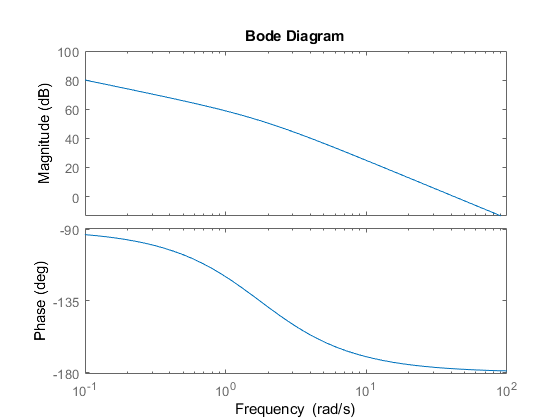

load Lab2W19.mat
Je = 5.6636e-4;
Be = 9.9236e-4;
sys = tf(1, [Je Be 0]);
bode(sys)

## Plot Data given/ Attempt to find TF from data

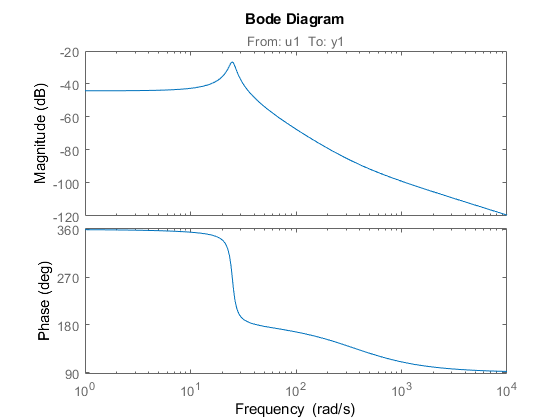

x = Frequency;
y = zeros(length(Frequency), 1); % Table response
z = zeros(length(Frequency), 1); % Motor Response
for i = 1:length(Frequency)
    y(i) = LinearComplex(:,:,i);
    z(i) = RotaryComplex(:,:,i);
end
Ts = 0.001;
data_table = iddata(y,x,Ts,'Frequency',x);
sys_table = tfest(data_table, 2);
data_motor = iddata(z,x,Ts,'Frequency',x);
sys_motor = tfest(data_motor, 2);

bode(sys_table)

% bode(sys_motor)
% semilogx(Frequency, abs(y))
% semilogx(Frequency, angle(y))
% semilogx(Frequency, abs(z))
% semilogx(Frequency, angle(z))

## PID Controller

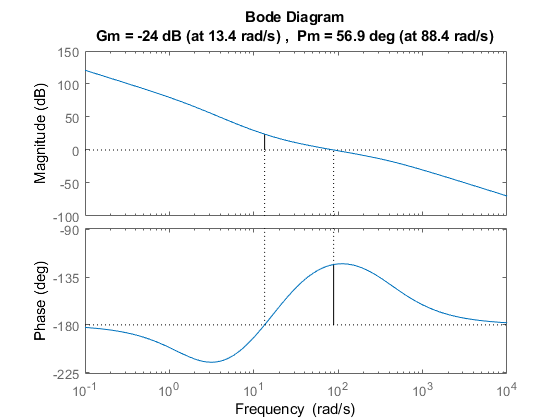

Wc_1 = 15*2*pi;
Wc_2 = 30*2*pi;
alpha = 4; % PM of 60deg

% Controller 

C_I_1 = (Wc_1 + Wc_1/10)/Wc_1;
C_LL_1 = (alpha + 1)/((1/alpha) + 1);
C_1 = C_I_1*C_LL_1;
G_1 = 1/(Wc_1*(Je*Wc_1 + Be));
% G_1 = interp1(x,abs(y),Wc_1);
Kc_1 = 1/(C_1*G_1);

C_I_2 = (Wc_2 + Wc_2/10)/Wc_2;
C_LL_2 = (alpha + 1)/((1/alpha) + 1);
C_2 = C_I_2*C_LL_2;
% G_2 = interp1(x,abs(y),Wc_2);
G_2 = 1/(Wc_2*(Je*Wc_2 + Be));
Kc_2 = 1/(C_2*G_2);

C_1_TF_I = tf([1 Wc_1/10],[1 0]);
C_1_TF_LL = tf([alpha/Wc_1 1], [1/(alpha*Wc_1) 1]);
C_1_TF = Kc_1*C_1_TF_I*C_1_TF_LL;
sys_C1 = sys*C_1_TF;
margin(sys_C1)

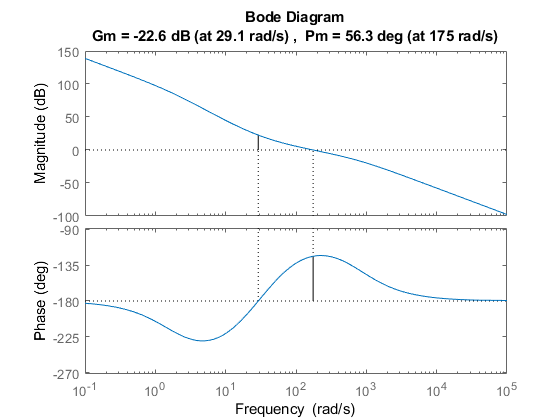


C_2_TF_I = tf([1 Wc_2/10],[1 0]);
C_2_TF_LL = tf([alpha/Wc_2 1], [1/(alpha*Wc_2) 1]);
C_2_TF = Kc_2*C_2_TF_I*C_2_TF_LL;
sys_C2 = sys*C_2_TF;
margin(sys_C2)

## P-PI Controller